# Dynamics Simulation 

Dynamic Simulation for the 2 DoF Space Robot

clc
load 'SC_2DoF.mat'

sc.homeConfig();

Specify Forces

f0 = [0; 0; 0];     % Forces on base [fx, fy, fz], in base frame
n0 = [0; 0; 0];     % Torques on base [nx, ny, nz], in base frame
tau_qm = [0; 1];      % Joint torques

### Launch Simulation

% profile on
tic
simRes = sim('sim_test');
toc

Elapsed time is 2.079481 seconds.


% profile viewer
% profile off

### Animate Results

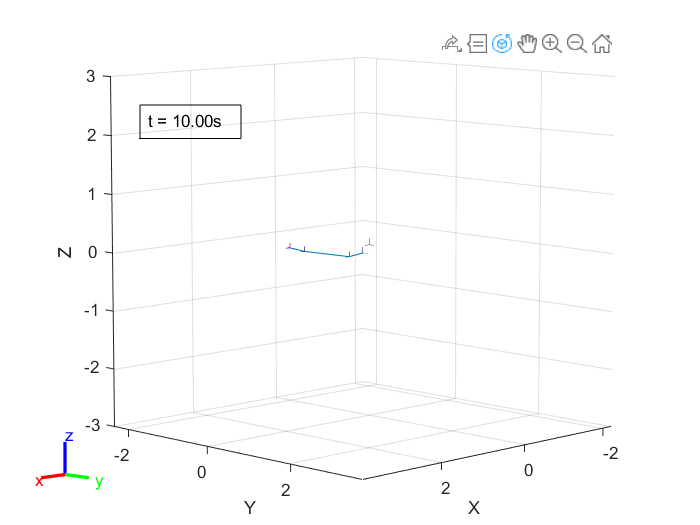

dim = [.2 .5 .3 .3];

tic
framesPerSecond = length(simRes.tout)/simRes.tout(end);
r = rateControl(framesPerSecond);
for i = 1:length(simRes.q.Time)
    sc.q = simRes.q.Data(:, :, i);
    sc.show('PreservePlot',false, 'Visuals', 'off');
    curT = i/framesPerSecond;
    str = sprintf('t = %.2fs', curT);
    annotation('textbox',dim,'String',str,'FitBoxToText','on');
    drawnow
    waitfor(r);
end

toc

Elapsed time is 85.951174 seconds.


r.TotalElapsedTime

ans = 85.9488